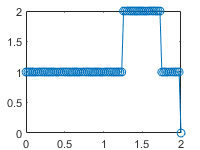

clear; clc;
N = 81; c=1;
x = linspace(0,2,N+1); 
dx= 0.025;
dt=dx; 
tf=30*dt;
M=tf/dt;
%++++++++++++++++++++++++++++++++++++++++++++++++
u = ones(N+1,1);
for i=1:N+1
	if x(i)>0.5 && x(i)<1
		u(i)=2;
	end
end
%++++++++++++++++++++++++++++++++++++++++++++++++
for n=1:M
	un=u;
    for i=2:N
		u(i)=(un(i-1)+un(i+1))/2-(c*dt/(2*dx))*(un(i+1)-un(i-1)) ;
    end
    u(N+1)=0;
    u(1)=1;
    plot(x,u,'-o')
    pause(0.2)
end